Loading C19 Data from JHU. 

confirmed = loadData('confirmed')

confirmed = 266×183 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36

deaths = loadData('deaths')

deaths = 266×183 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36   

recovered = loadData('recovered')

recovered = 253×183 table
            ProvinceState                CountryRegion         Lat       Long      Var5    Var6    Var7    Var8    Var9    Var10    Var11    Var12    Var13    Var14    Var15    Var16    Var17    Var18    Var19    Var20    Var21    Var22    Var23    Var24    Var25    Var26    Var27    Var28    Var29    Var30    Var31    Var32    Var33    Var34    Var35    Var36

beta = 1

beta = 1

vega = .5

vega = 0.5000


population = 7.5*10^9

population = 7.5000e+09

I_t = sum(confirmed{:,end},1)

I_t = 14288689

R_t = sum(deaths{:,end},1) + sum(confirmed{:,end},1)

R_t = 14890827

S_t = population - I_t - R_t

S_t = 7.4708e+09


A = [transpose(S_t), transpose(I_t), transpose(R_t)]

A = 	1.0e+09 *

    7.4708    0.0143    0.0149



s_t = [S_t/population]

s_t = 0.9961

i_t = [I_t/population]

i_t = 0.0019

r_t = [R_t * 1/population]

r_t = 0.0020


ds_dt = -1 * beta * s_t .* i_t

ds_dt = -0.0019

dr_dt = (vega * i_t)

dr_dt = 9.5258e-04

di_dt = (-1 * ds_dt) - (dr_dt)

di_dt = 9.4517e-04

figure
hold on
region = 12

region = 12

t = 12:width(confirmed)

t =     12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61


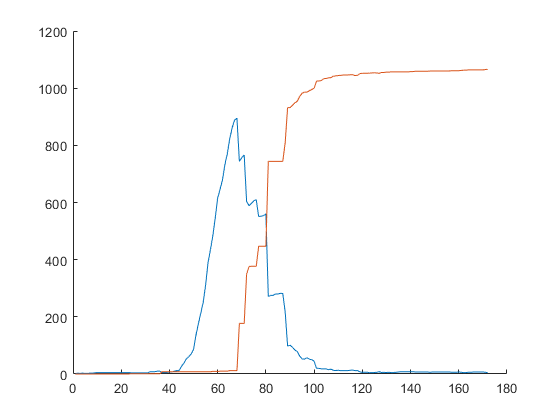

%plot(5072000-confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(confirmed{region,t}-deaths{region,t}-recovered{region,t})
plot(deaths{region,t}+recovered{region,t})

[pks, locs] = findpeaks(confirmed{region,t}-deaths{region,t}-recovered{region,t})

pks =      3     3     5    10   895   766   610   560   282   101    57    17    13    14     8     6     6     8     7     7     7


locs =      2     4    10    35    68    71    76    80    86    90    97   107   110   116   127   129   131   136   149   160   166


%Initial attempt at Jacobian
br = 0;
a = 0.5;
b = 0.98;
u = 1 - b;
t=20;
region = 12;
qlpop = 5072000;
s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t}

s1 = 5071996

i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t}

i1 = 4

r1 = deaths{region,t} + recovered{region,t}

r1 = 0

J = [-a*i1-u -a*s1 0; a*i1 a*s1-b-u 0; 0 b -u];
[V,D] = eig(J)

V =          0   -0.7071    0.7071
         0    0.7071   -0.0000
    1.0000    0.0000   -0.7071


D = 	1.0e+06 *

   -0.0000         0         0
         0    2.5360         0
         0         0   -0.0000


qlpop = 5072000

qlpop = 5072000

d1 = 12

d1 = 12

s1 = qlpop - confirmed{12,12} - deaths{12,12} - recovered{12,12}

s1 = 5071999

i1 = confirmed{12,12} - deaths{12,12} - recovered{12,12}

i1 = 1

r1 = deaths{12,12} + recovered{12,12}

r1 = 0

g1 = [s1 i1 r1]

g1 =      5071999           1           0


d2 = 50

d2 = 50

s2 = qlpop - confirmed{12,d2} - deaths{12,d2} - recovered{12,d2}

s2 = 5071979

i2 = confirmed{12,d2} - deaths{12,d2} - recovered{12,d2}

i2 = 5

r2 = deaths{12,d2} + recovered{12,d2}

r2 = 8

g2 = [s2 i2 r2]

g2 =      5071979           5           8


M = [s2/s1 (s2-s1)/s1 0; 0 (i2-r2)/i2 (r2-r1)/r2; 0 0 1]

M =     1.0000   -0.0000         0
         0   -0.6000    1.0000
         0         0    1.0000
